Qualtrics Pilot

% Use if loading script from GitHub
fname = matlab.desktop.editor.getActiveFilename();
fdir = fileparts(fname);
cd(fdir);
cd ..\data
load('pilot_master_long.mat')

master = sortrows(master,"Pair","ascend");

cuehl = master.highcue_indx;
cuemean = master.cue_observed_mean;
pair = master.Pair;
rating = master.img_rate;
stimmean = master.Valence_mean;

wh_high = cuehl > 0;
wh_low = cuehl < 0;

hi_table = master(wh_high, :);
lo_table = master(wh_low, :);



pair_table = table();
pair_table.pair_number = hi_table.Pair;
pair_table.hi_val = hi_table.img_rate;
pair_table.lo_val = lo_table.img_rate;
pair_table.rating_mean = (hi_table.img_rate + lo_table.img_rate)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.img_rate - lo_table. img_rate;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
pair_table.norm_hi = pair_table.hi_val - pair_table.rating_mean;
pair_table.norm_lo = pair_table.lo_val - pair_table.rating_mean;


data = pair_table;

% Specify the number of rows in each section
sectionSize = 123; % create an 'nsub' variable later

% Calculate the number of sections
numSections = ceil(size(data, 1) / sectionSize);

% Initialize a cell array to store the section averages for each column
sectionAverages = cell(1, numSections);

% Calculate the average for each column
for i = 1:numSections
    % Determine the row indices for the current section
    startIndex = (i - 1) * sectionSize + 1;
    endIndex = min(i * sectionSize, size(data, 1));
    
    % Extract the current section as a sub-table
    currentSection = data(startIndex:endIndex, :);
    
    % Calculate the average for each column in the section
    sectionAverage = mean(currentSection{:, :});
    
    % Store the section average in the cell array
    sectionAverages{i} = sectionAverage;
end

averageMatrix = cell2mat(sectionAverages');
pair_table = array2table(averageMatrix, 'VariableNames', data.Properties.VariableNames);
d = pair_table.rating_diff;


% Two-tailed
[hyp, pval, ci, stat] = ttest(pair_table.hi_val, pair_table.lo_val, 'Tail', 'both');
fprintf('High vs. low cue effect: M = %3.2f, SE = %3.2f, t(%3.0f) = %3.2f, p = %3.6f\n', mean(d), ste(d), stat.df(1), stat.tstat(1), pval(1));

High vs. low cue effect: M = 4.18, SE = 0.29, t( 31) = 14.34, p = 0.000000



allsubmean = mean(pair_table.rating_diff)

allsubmean = 4.1845

allsubci = ci

allsubci =     3.5894
    4.7795


allsubSE = ste(d)

allsubSE = 0.2918

allsubpairtable = pair_table;


Averge Effect: 

% % Extract and compute normative H-L cue picture rating differences
normative_diff = pair_table.stim_diff;
% 
% Perform the regression model
X = [ones(size(normative_diff, 1), 1), normative_diff];
y = pair_table.rating_diff;
coeffs = regress(y, X);

% Extract the intercept term (effect of interest)
intercept = coeffs(1);

% Display the results
fprintf('Intercept (average H-L cue effect): %.4f\n', intercept);

Intercept (average H-L cue effect): 4.1243




% figure; hold on;
% y = [mean(allsubpairtable.lo_val); mean(allsubpairtable.rating_diff)];
% errlow = mean(allsubpairtable.rating_diff)-allsubSE
% errhigh = mean(allsubpairtable.rating_diff)+allsubSE
% 
% er = errorbar(mean(allsubpairtable.hi_val), errlow,errhigh);    
% er.Color = [0 0 0];                            
% er.LineStyle = 'none'; 
% 
% set(gca, 'FontSize', 24)
% scn_export_papersetup(400);
% ylabel('Percent Change');
% % xlabel('Subject Number');
% title('t-values for h - L within pair')
% % set(gca, 'YTick', 1:5:28, 'YTickLabel', imgview_freq.freq);
% hold off;

Cue Effect (ordered by pair number)

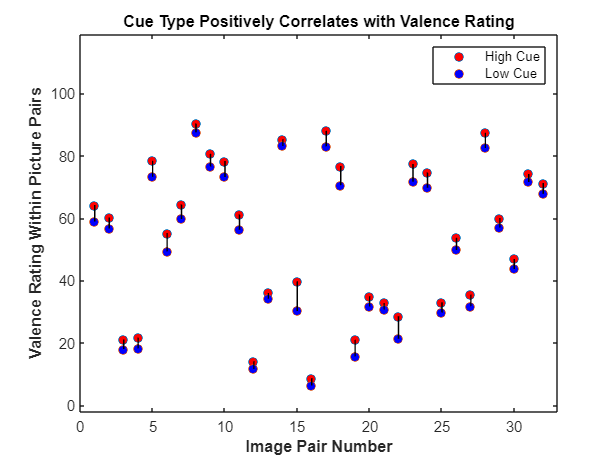

%%

pair_table = sortrows(pair_table, "pair_number", "ascend");
pairs = [1:32]';

y = [pair_table.hi_val pair_table.lo_val];
x = [pairs pairs];  % pairs, [high low]

figure;

highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

title('Cue Type Positively Correlates with Valence Rating')
xlabel('Image Pair Number', 'FontWeight','bold');
ylabel('Valence Rating Within Picture Pairs', 'FontWeight','bold')
hold off;

axis([0 33 -2 119])

ax = gca;
% ax.FontSize = 20;
legend([highdots lowdots], {'High Cue', 'Low Cue'})

I think that there's something interesting happening when individuals have strong pre-existing preferences for an image. I'll try to quantify that by looking at ratings that are more than 2 SD away from the normative mean. 

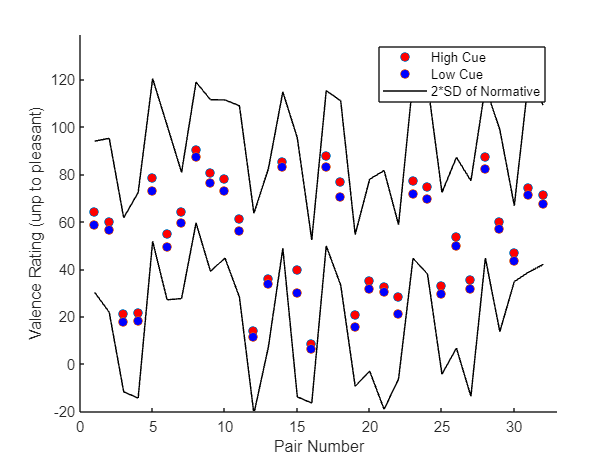

hi_sd = pair_table.stim_mean + (2*pair_table.stim_sd);
lo_sd = pair_table.stim_mean - (2*pair_table.stim_sd);

figure; hold on;
highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

% meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');

sd_up = plot(hi_sd, 'k-');
sd_down = plot(lo_sd, 'k-');

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')

axis([0 33 -20 139])
legend([highdots lowdots sd_up], {'High Cue', 'Low Cue', '2*SD of Normative'})
hold off;

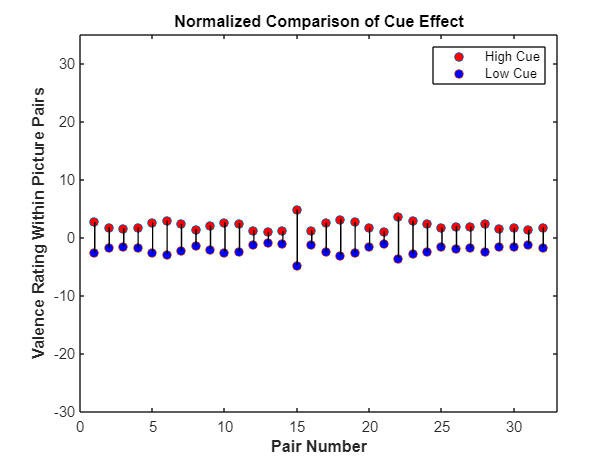


% pair_table = sortrows(pair_table, "rating_diff", "ascend");
pairs = [1:32]';

y = [pair_table.hi_val-pair_table.rating_mean pair_table.lo_val-pair_table.rating_mean];  % ratings, [high low]
x = [pairs pairs];  % pairs, [high low]


figure;

highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

title('Normalized Comparison of Cue Effect')
xlabel('Pair Number', 'FontWeight','bold');
ylabel('Valence Rating Within Picture Pairs','FontWeight','bold')
hold off;

axis([0 33 -30 35])

ax = gca;
% ax.FontSize = 20;
legend([highdots lowdots], {'High Cue', 'Low Cue'})

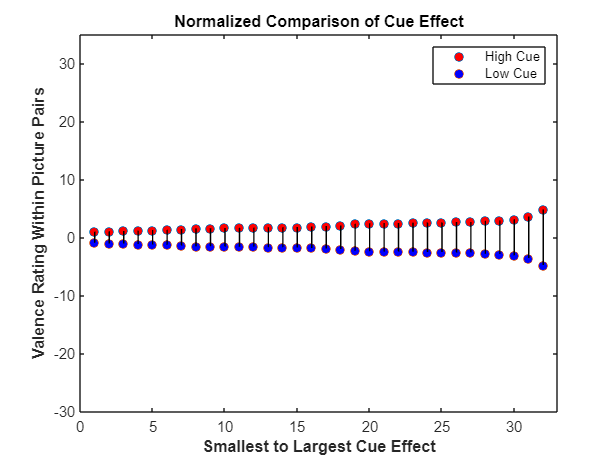


pair_table = sortrows(pair_table, "rating_diff", "ascend");
pairs = [1:32]';

y = [pair_table.hi_val-pair_table.rating_mean pair_table.lo_val-pair_table.rating_mean];  % ratings, [high low]
x = [pairs pairs];  % pairs, [high low]


figure;

highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

title('Normalized Comparison of Cue Effect')
xlabel('Smallest to Largest Cue Effect', 'FontWeight','bold');
ylabel('Valence Rating Within Picture Pairs','FontWeight','bold')
hold off;

axis([0 33 -30 35])

ax = gca;
% ax.FontSize = 20;
legend([highdots lowdots], {'High Cue', 'Low Cue'})

Cue Effect (ordered from largest to smallest)

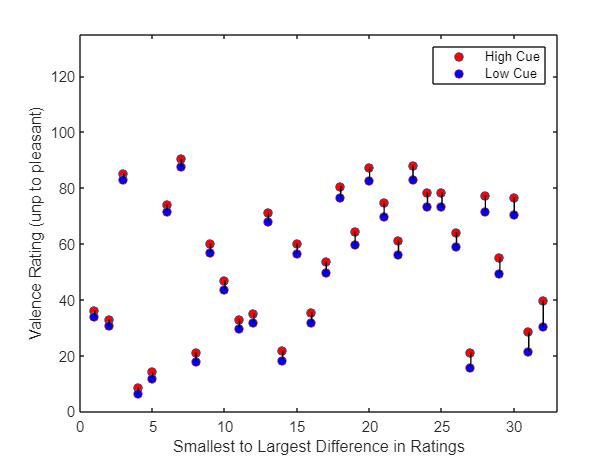

pair_table = sortrows(pair_table,"rating_diff","ascend");

pairs = [1:32]';

y = [pair_table.hi_val pair_table.lo_val];  % ratings, [high low]
x = [pairs pairs];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);


xlabel('Smallest to Largest Difference in Ratings');
ylabel('Valence Rating (unp to pleasant)')
title('')
hold off;

axis([0 33 0 135])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

Control of Cue Effect 

% % y = [hi_table.Valence_mean lo_table.Valence_mean];  % ratings, [high low]
% % x = [hi_table.Pair lo_table.Pair];  % pairs, [high low]
% 
% figure;
% highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;
% 
% lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); hold off;
% 
% xlabel('Pair Number');
% ylabel('Valence Rating (unp to pleasant)')
% title('Normative Valence Ratings (Positive control)')
% hold off;
% axis([0 33 0 120])
% legend([highdots lowdots], {'High Cue', 'Low Cue'})